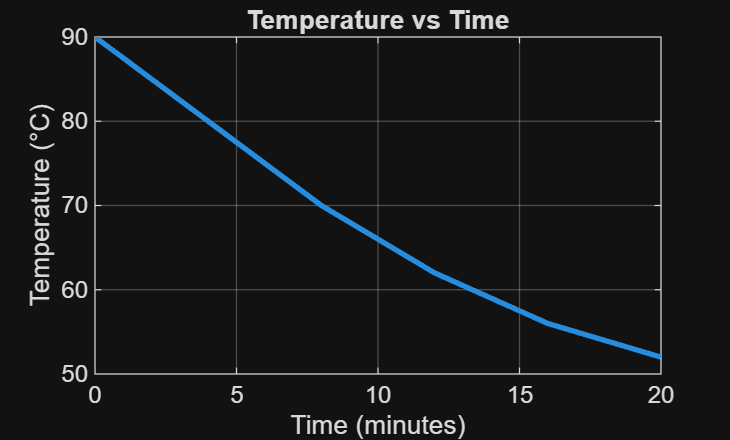

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 9 Project: Cooling Curve Approximation 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Time vector (minutes) 
t = 0:2:20; 
 
% ---------------------------- 
% Temperature data (decreasing) 
T = [90 85 80 75 70 66 62 59 56 54 52]; 
 
% ---------------------------- 
% Plot temperature vs time 
figure; 
plot(t, T, 'LineWidth', 2); 
 
title('Temperature vs Time'); 
xlabel('Time (minutes)'); 
ylabel('Temperature (°C)'); 
grid on; 

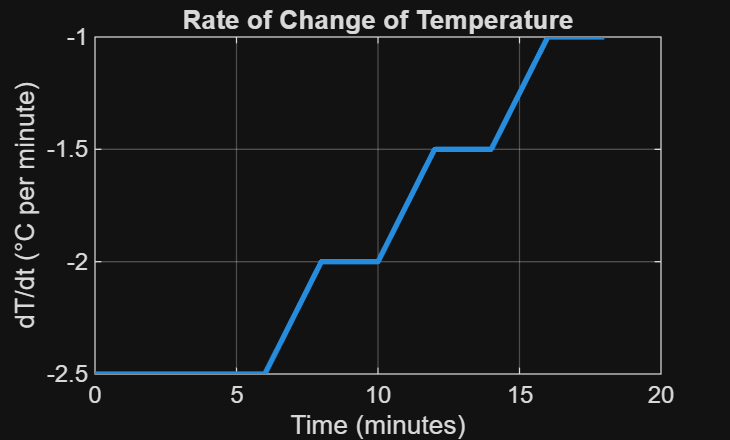

 
% ---------------------------- 
% Rate of change (finite differences) 
dt = 2; 
dT = diff(T) / dt; 
 
% Adjust time for derivative 
t_rate = t(1:end-1); 
 
% Plot rate of change 
figure; 
plot(t_rate, dT, 'LineWidth', 2); 
 
title('Rate of Change of Temperature'); 
xlabel('Time (minutes)'); 
ylabel('dT/dt (°C per minute)'); 
grid on; 

 
% ---------------------------- 
% Total thermal exposure (area under curve) 
area = trapz(t, T); 
 
fprintf('Estimated total thermal exposure: %.2f\n', area); 

Estimated total thermal exposure: 1356.00
